# Module 1 Quiz

data = importFlightsData('Flights\flightsJan.csv')

data = 469968×20 table
         AIRLINE         TAIL_NUMBER    FLIGHT_NUMBER    ORIGIN    DESTINATION    SCHEDULED_DEPARTURE_TIME    ACTUAL_DEPARTURE_TIME    DEPARTURE_DELAY    TAXI_OUT    AIR_TIME    TAXI_IN    SCHEDULED_ARRIVAL_TIME    ACTUAL_ARRIVAL_TIME     ARRIVAL_DELAY    SCHEDULED_ELAPSED_TIME    ACTUAL_ELAPSED_TIME    DISTANCE    CANCELLED    CANCELLATION_CODE    DIVERTED
    _________________    ___________    _____________    ______    ___________    ________________________    _____________________    _______________

temp = groupsummary(data, 'ORIGIN');
temp = sortrows(temp, 'GroupCount', 'descend');
temp(1, 1)

ans = table
    ORIGIN
    ______

     ATL  


clearvars -except data

temp = groupsummary(data, 'ORIGIN', 'mean', 'DISTANCE');
temp = sortrows(temp, 'mean_DISTANCE');
temp(1, :)

ans = 1×3 table
    ORIGIN    GroupCount    mean_DISTANCE
    ______    __________    _____________

     WRG          62            56.5     


clearvars -except data

temp = groupsummary(data, 'CANCELLATION_CODE');
temp = temp(temp.CANCELLATION_CODE == 'A' ...
    | temp.CANCELLATION_CODE == 'B' ...
    | temp.CANCELLATION_CODE == 'C' ...
    | temp.CANCELLATION_CODE == 'D', :);
temp = sum(temp.GroupCount)

temp = 11982

clearvars -except data

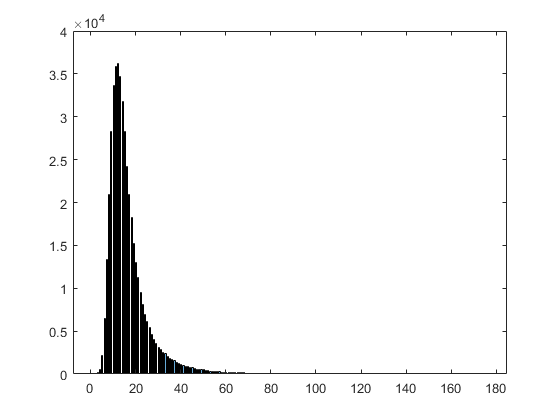

histogram(data.TAXI_OUT)

clearvars